emb = fastTextWordEmbedding;

filenameTrain = "lessonlearnedTrain.csv";
textName = "event_narrative";
labelName = "event_type";
ttdsTrain = tabularTextDatastore(filenameTrain,'SelectedVariableNames',[textName labelName]);

textName2 = "abstract";
labelName2 = "safety";
ttdsTrain2 = tabularTextDatastore(filenameTrain,'SelectedVariableNames',[textName2 labelName2]);

ttdsTrain.ReadSize = 8;
preview(ttdsTrain)

ans = 8×2 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                  event_narrative                                                                                                                                                                                                                                                                                                                      

ttdsTrain2.ReadSize = 8;
preview(ttdsTrain2)

ans = 8×2 table
                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                    abstract                                                                                                                                                                                                                                                                                                                                                                                                                                                                           

labels = readLabels(ttdsTrain,labelName);
classNames = unique(labels);
numObservations = numel(labels);

labels2 = readLabels(ttdsTrain2,labelName2);
classNames2 = unique(labels2);
numObservations2 = numel(labels2);
sequenceLength = 100;
tdsTrain = transform(ttdsTrain, @(data) transformTextData(data,sequenceLength,emb,classNames))

tdsTrain =   TransformedDatastore with properties:

    UnderlyingDatastore: [1×1 matlab.io.datastore.TabularTextDatastore]
             Transforms: {@(data)transformTextData(data,sequenceLength,emb,classNames)}
            IncludeInfo: 0


tdsTrain2 = transform(ttdsTrain2, @(data) transformTextData(data,sequenceLength,emb,classNames2))

tdsTrain2 =   TransformedDatastore with properties:

    UnderlyingDatastore: [1×1 matlab.io.datastore.TabularTextDatastore]
             Transforms: {@(data)transformTextData(data,sequenceLength,emb,classNames2)}
            IncludeInfo: 0


preview(tdsTrain)

ans = 8×2 table
        predictors                   responses            
    __________________    ________________________________

    [1×100×300 single]    Aeronautics Research            
    [1×100×300 single]    Human Exploration and Operations
    [1×100×300 single]    Aeronautics Research            
    [1×100×300 single]    Human Exploration and Operations
    [1×100×300 single]    Aeronautics Research            
    [1×100×300 single]    Human Exploration and Operations
    [1×100×300 single]    Human Exploration and Operations
    [1×100×300 single]    Aeronautics Research            


preview(tdsTrain2)

ans = 8×2 table
        predictors        responses
    __________________    _________

    [1×100×300 single]      TRUE   
    [1×100×300 single]      FALSE  
    [1×100×300 single]      TRUE   
    [1×100×300 single]      FALSE  
    [1×100×300 single]      FALSE  
    [1×100×300 single]      FALSE  
    [1×100×300 single]      TRUE   
    [1×100×300 single]      FALSE  


filenameValidation = "lessonlearnedTest.csv";
ttdsValidation = tabularTextDatastore(filenameValidation,'SelectedVariableNames',[textName labelName]);

ttdsValidation2 = tabularTextDatastore(filenameValidation,'SelectedVariableNames',[textName2 labelName2]);


tdsValidation = transform(ttdsValidation, @(data) transformTextData(data,sequenceLength,emb,classNames))

tdsValidation =   TransformedDatastore with properties:

    UnderlyingDatastore: [1×1 matlab.io.datastore.TabularTextDatastore]
             Transforms: {@(data)transformTextData(data,sequenceLength,emb,classNames)}
            IncludeInfo: 0


tdsValidation2 = transform(ttdsValidation2, @(data) transformTextData(data,sequenceLength,emb,classNames2))

tdsValidation2 =   TransformedDatastore with properties:

    UnderlyingDatastore: [1×1 matlab.io.datastore.TabularTextDatastore]
             Transforms: {@(data)transformTextData(data,sequenceLength,emb,classNames2)}
            IncludeInfo: 0


numFeatures = emb.Dimension;
inputSize = [1 sequenceLength numFeatures];
numFilters = 200;

ngramLengths = [2 3 4 5];
numBlocks = numel(ngramLengths);

numClasses = numel(classNames);
numClasses2 = numel(classNames2);

Create a layer graph containing the input layer. Set the normalization option to `'none'` and the layer name to `'input'`.

layer = imageInputLayer(inputSize,'Normalization','none','Name','input');
lgraph = layerGraph(layer);

layer2 = imageInputLayer(inputSize,'Normalization','none','Name','input');
lgraph2 = layerGraph(layer2);

for j = 1:numBlocks
    N = ngramLengths(j);
    
    block = [
        convolution2dLayer([1 N],numFilters,'Name',"conv"+N,'Padding','same')
        batchNormalizationLayer('Name',"bn"+N)
        reluLayer('Name',"relu"+N)
        dropoutLayer(0.2,'Name',"drop"+N)
        maxPooling2dLayer([1 sequenceLength],'Name',"max"+N)];
    
    lgraph = addLayers(lgraph,block);
    lgraph = connectLayers(lgraph,'input',"conv"+N);
       
end

for j = 1:numBlocks
    N = ngramLengths(j);
    
    block = [
        convolution2dLayer([1 N],numFilters,'Name',"conv"+N,'Padding','same')
        batchNormalizationLayer('Name',"bn"+N)
        reluLayer('Name',"relu"+N)
        dropoutLayer(0.2,'Name',"drop"+N)
        maxPooling2dLayer([1 sequenceLength],'Name',"max"+N)];
    
    lgraph2 = addLayers(lgraph2,block);
    lgraph2 = connectLayers(lgraph2,'input',"conv"+N);
       
end

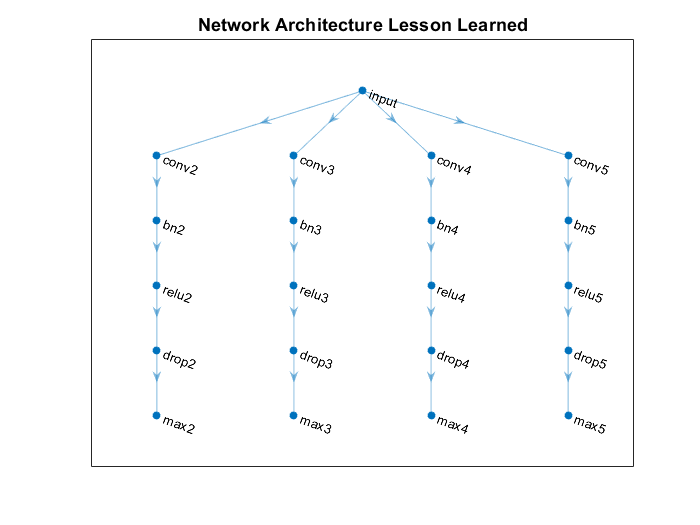

figure
plot(lgraph)
title("Network Architecture Lesson Learned")

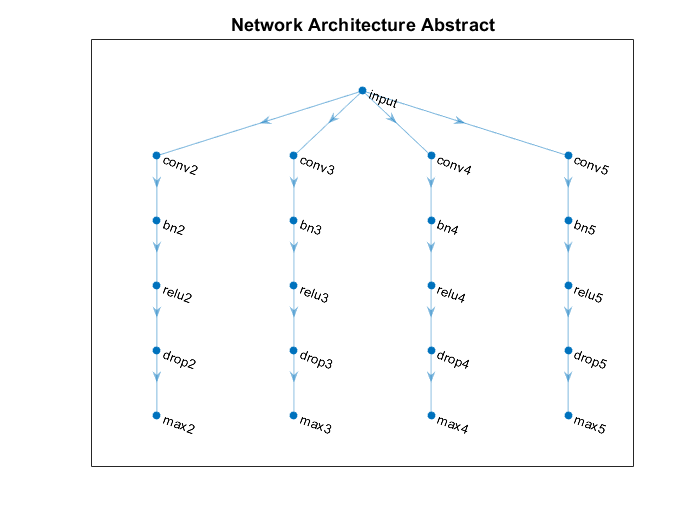

figure
plot(lgraph2)
title("Network Architecture Abstract")

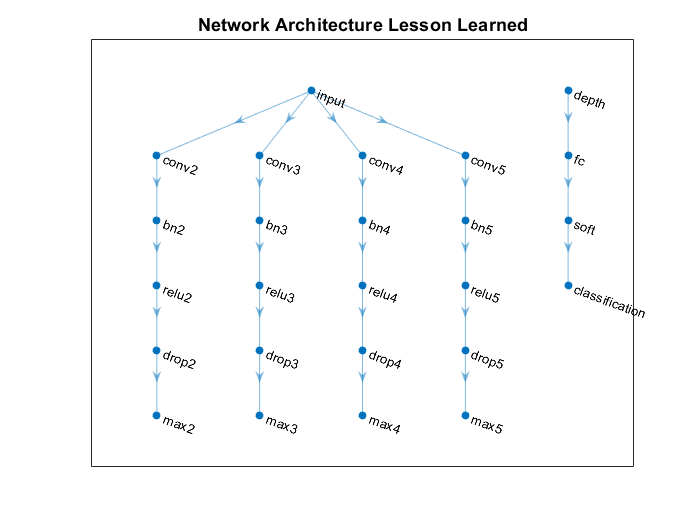

layers = [
    depthConcatenationLayer(numBlocks,'Name','depth')
    fullyConnectedLayer(numClasses,'Name','fc')
    softmaxLayer('Name','soft')
    classificationLayer('Name','classification')];

lgraph = addLayers(lgraph,layers);

figure
plot(lgraph)
title("Network Architecture Lesson Learned")

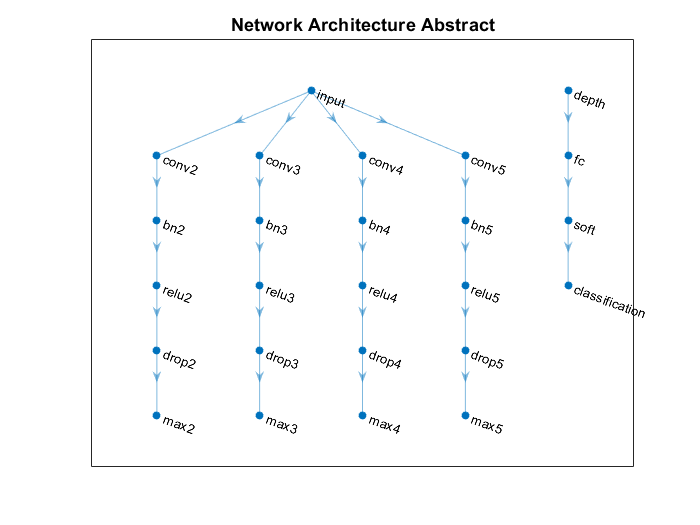

layers2 = [
    depthConcatenationLayer(numBlocks,'Name','depth')
    fullyConnectedLayer(numClasses2,'Name','fc')
    softmaxLayer('Name','soft')
    classificationLayer('Name','classification')];

lgraph2 = addLayers(lgraph2,layers2);

figure
plot(lgraph2)
title("Network Architecture Abstract")

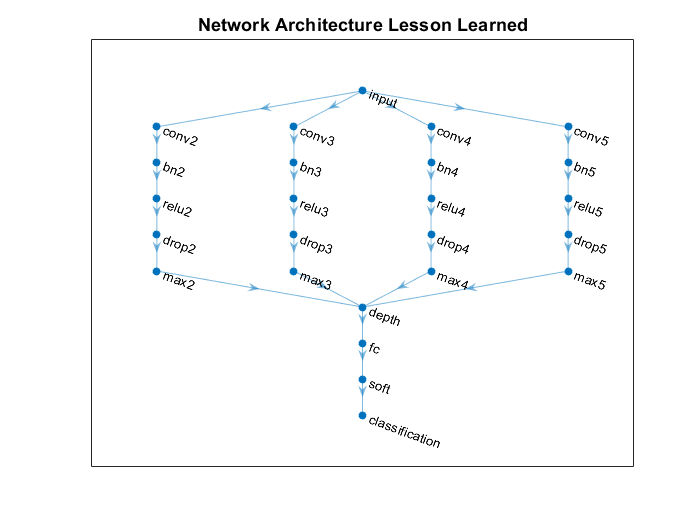

for j = 1:numBlocks
    N = ngramLengths(j);
    lgraph = connectLayers(lgraph,"max"+N,"depth/in"+j);
end

figure
plot(lgraph)
title("Network Architecture Lesson Learned")

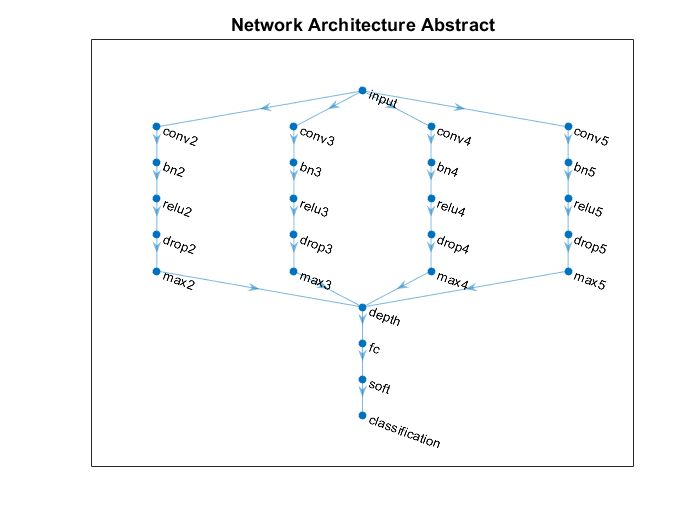


for j = 1:numBlocks
    N = ngramLengths(j);
    lgraph2 = connectLayers(lgraph2,"max"+N,"depth/in"+j);
end

figure
plot(lgraph2)
title("Network Architecture Abstract")

miniBatchSize = 128;
numIterationsPerEpoch = floor(numObservations/miniBatchSize);

options = trainingOptions('adam', ...
    'MaxEpochs',10, ...
    'MiniBatchSize',miniBatchSize, ...
    'ValidationData',tdsValidation, ...
    'ValidationFrequency',numIterationsPerEpoch, ...
    'Plots','training-progress', ...
    'Verbose',false);

numIterationsPerEpoch2 = floor(numObservations2/miniBatchSize);

options2 = trainingOptions('adam', ...
    'MaxEpochs',10, ...
    'MiniBatchSize',miniBatchSize, ...
    'ValidationData',tdsValidation2, ...
    'ValidationFrequency',numIterationsPerEpoch2, ...
    'Plots','training-progress', ...
    'Verbose',false);

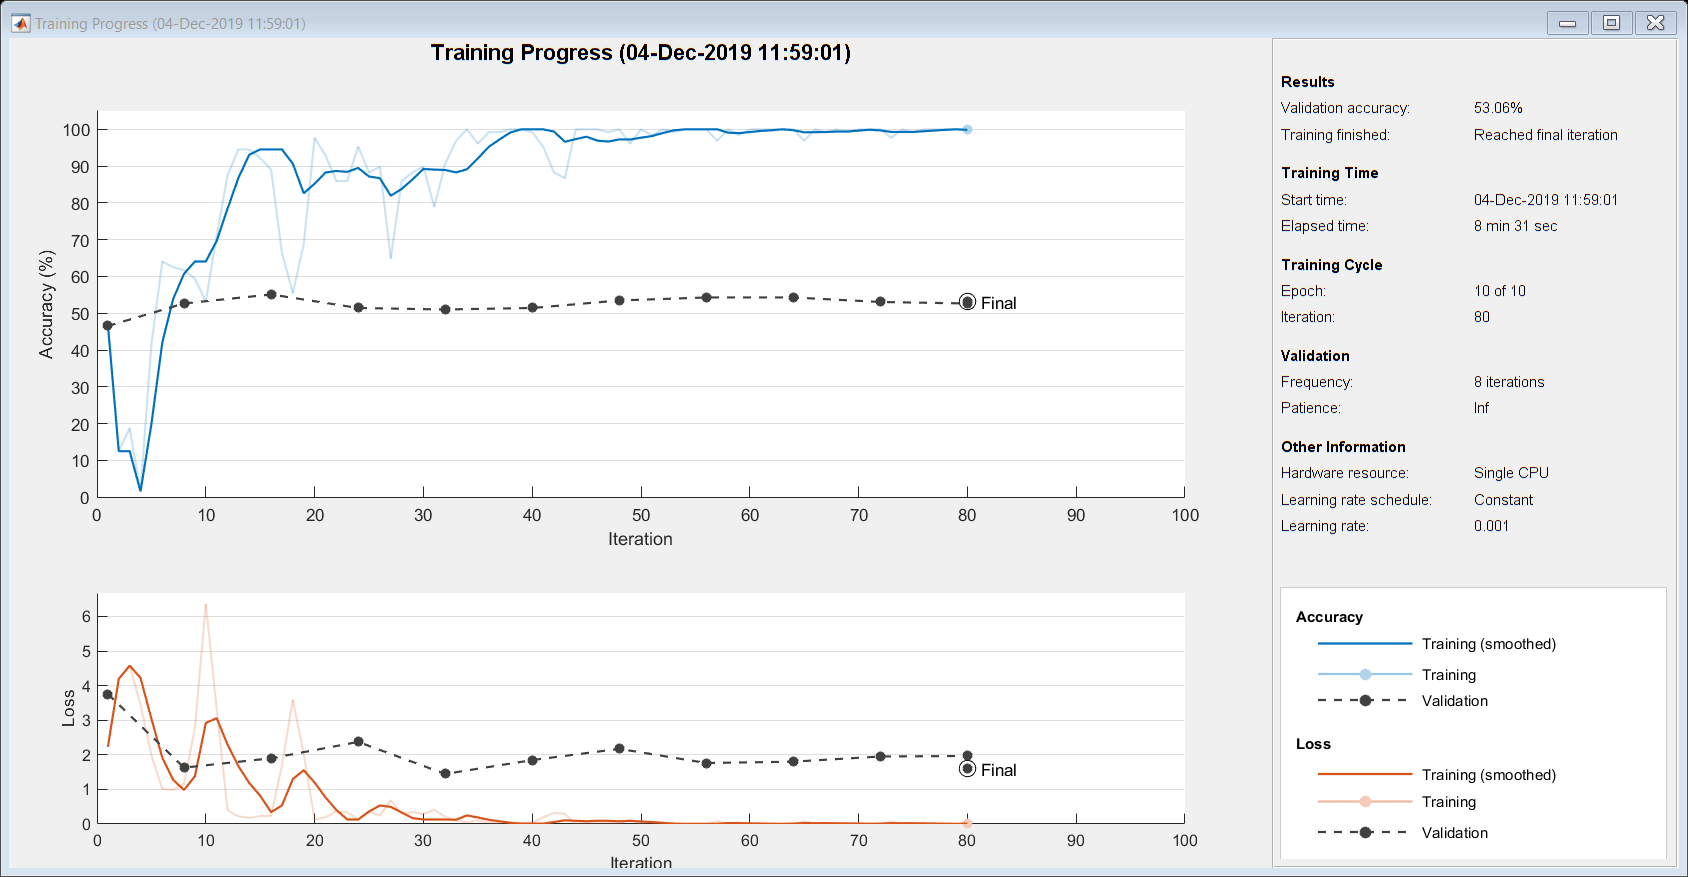

net = trainNetwork(tdsTrain,lgraph,options);

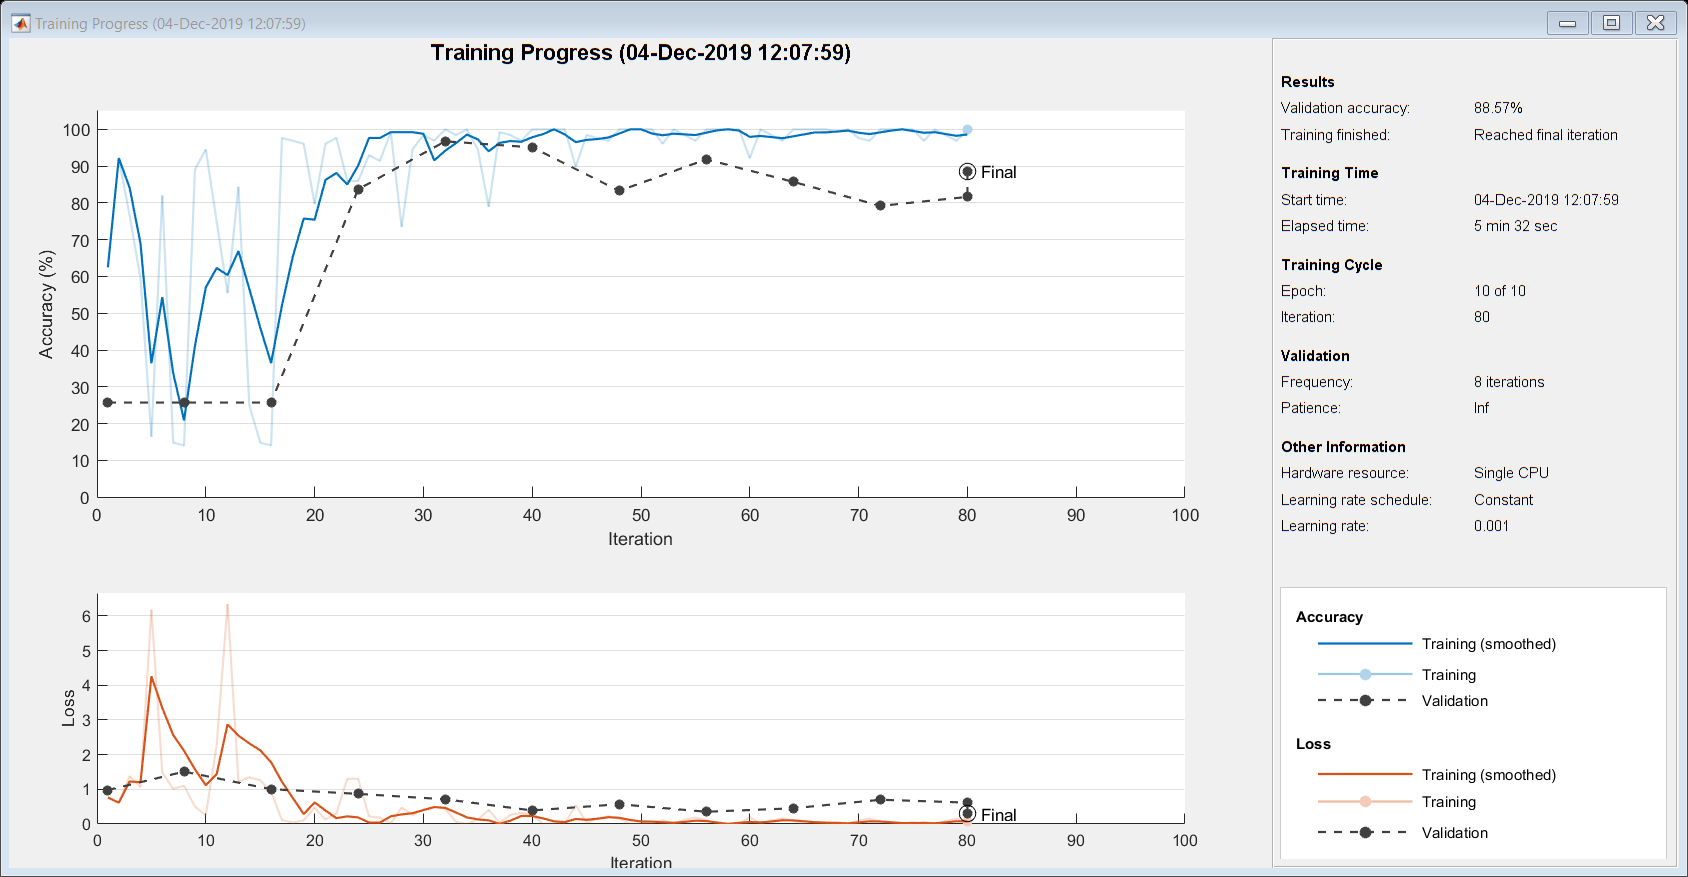

net2 = trainNetwork(tdsTrain2,lgraph2,options2);

filenameTest = "lessonlearnedValidation.csv";
ttdsTest = tabularTextDatastore(filenameTest,'SelectedVariableNames',[textName labelName]);

tdsTest = transform(ttdsTest, @(data) transformTextData(data,sequenceLength,emb,classNames))

tdsTest =   TransformedDatastore with properties:

    UnderlyingDatastore: [1×1 matlab.io.datastore.TabularTextDatastore]
             Transforms: {@(data)transformTextData(data,sequenceLength,emb,classNames)}
            IncludeInfo: 0



ttdsTest2 = tabularTextDatastore(filenameTest,'SelectedVariableNames',[textName2 labelName2]);

tdsTest2 = transform(ttdsTest2, @(data) transformTextData(data,sequenceLength,emb,classNames2))

tdsTest2 =   TransformedDatastore with properties:

    UnderlyingDatastore: [1×1 matlab.io.datastore.TabularTextDatastore]
             Transforms: {@(data)transformTextData(data,sequenceLength,emb,classNames2)}
            IncludeInfo: 0


labelsTest = readLabels(ttdsTest,labelName);
YTest = categorical(labelsTest,classNames);

labelsTest2 = readLabels(ttdsTest2,labelName2);
YTest2 = categorical(labelsTest2,classNames2);

YPred = classify(net,tdsTest);
YPred2 = classify(net2,tdsTest2);

accuracy = mean(YPred == YTest)

accuracy = 0.5592

accuracy2 = mean(YPred2 == YTest2)

accuracy2 = 0.7469

function labels = readLabels(ttds,labelName)

ttdsNew = copy(ttds);
ttdsNew.SelectedVariableNames = labelName;
tbl = readall(ttdsNew);
labels = tbl.(labelName);

end

function dataTransformed = transformTextData(data,sequenceLength,emb,classNames)


textData = data{:,1};
textData = lower(textData);
documents = tokenizedDocument(textData);


predictors = doc2sequence(emb,documents,'Length',sequenceLength);


predictors = cellfun(@(X) permute(X,[3 2 1]),predictors,'UniformOutput',false);


labels = data{:,2};
responses = categorical(labels,classNames);


dataTransformed = table(predictors,responses);

end